## Pharmacokinetics and pharmacodynamics of insulin

### Insulin absorption model (IAM)

### 1. Load data

PK

[t, i] = importPK('PK_a_PD_data/Dat_PK.csv'); % i - [pmol/L]

PD

[t_ra, ra] = importPD('PK_a_PD_data/Dat_PD.csv'); % ra - [mg/(kg*min)]

Given

bolus_ratio = 0.2;          % [IU/kg]
bolus = 12.88;              % [IU]
BW = 12.88 / 0.2;           % [kg]
bolus_rate = 1.09;          % [IU/h]

Conversion of units

i = i / 6;      % pmol/L to µIU/mL conversion given by Stanford lab
ra = ra / BW;       % [mg/(kgBW*min)]

### 2. Plot data from the PK

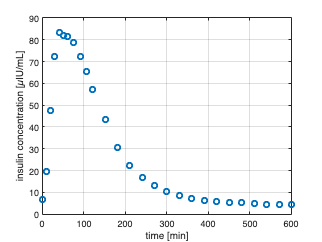

figure(1)
plot(t, i, 'o','Linewidth',2)
xlabel('time [min]'); ylabel('insulin concentration [µIU/mL]')

### 3. Compile a simulation scheme of IAM

open_system('iam_sim.slx')

Initialize variables

Ts = 5;
vB = bolus_ratio*1e6/Ts;    % [µIU/(kgBW*min)

%vb = bolus_rate*1e6/60/BW; % [µIU/(kgBW*min)
vb = 281.218;

v = [vB*ones(Ts,1); vb*ones(t(end)-Ts+1,1)];

v_sim.time = 0:t(end);
v_sim.signals.values = v;
v_sim.signals.dimensions = 1;

Initialize variables from literature

Ti = 44.55;                 % [min]
ki = 0.1645;                % [1/min]
Vi = 138.80;                % [mL/kg]

Set SIMULINK initials

S10 = Ti*vb;                % [µIU/kg]
S20 = S10;                  % [µIU/kg] 
I0 = 1/(ki*Vi*Ti)*S20;      % [µIU/mL]

Ib = 0; Gb = 0;
set_param('iam_sim/BMM', 'Commented', 'on')

input_sim.time = t_ra;
input_sim.signals.values = ra;
input_sim.signals.dimensions = 1;

### 4. Verify the simulation scheme

set_param('iam_sim/IAM/Gain_Ti', 'Gain', num2str(1/Ti));
set_param('iam_sim/IAM/Gain1_Ti', 'Gain', num2str(1/Ti));
set_param('iam_sim/IAM/Gain_ki', 'Gain', num2str(ki));
set_param('iam_sim/IAM/Gain_Vi', 'Gain', num2str(1/Vi));
set_param('iam_sim/IAM/Integrator_S1', ...
          'InitialCondition', num2str(S10));
set_param('iam_sim/IAM/Integrator_S2', ...
          'InitialCondition', num2str(S20));
set_param('iam_sim/IAM/Integrator_I', ...
          'InitialCondition', num2str(I0));

out0 = sim('iam_sim.slx');

### 5. Implement a identification method of Insulin Absorption Model parameters

Initialize optimized variables

theta0 = [Ti ki Vi];

Set optimization options

opts = optimset('Display', 'iter', 'MaxIter', 250);

Run identification

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          755.353         
     1            4          755.353         initial simplex
     2            5          755.353         reflect
     3            7          755.353         contract outside
     4            9          755.353         contract outside
     5           11          754.396         reflect
     6           13          751.278         contract inside
     7           15           749.82         contract inside
     8           17          746.929         reflect
     9           19          746.929         contract inside
    10           21          746.929         contract outside
    11           23          741.963         expand
    12           24          741.963         reflect
    13           25          741.963         reflect
    14           26          741.963         reflect
    15           28          740.435         reflect
    16           30          740.435        

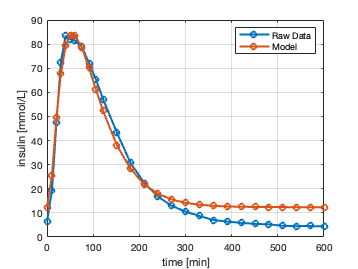

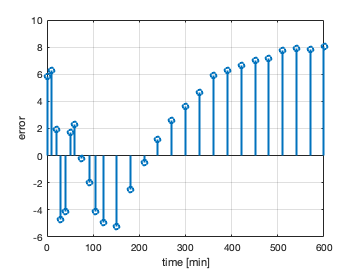

    77          156          737.366         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



x_opt =    43.8971    0.1356  167.6414


fval = 737.3663

exitflag = 1

output = struct with fields:
    iterations: 77
     funcCount: 156
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


[x_opt, fval, exitflag, output] = ...
    fminsearch(@objFcn_PK, theta0, opts, i, t, vb, 1)


Ti_opt = x_opt(1);
ki_opt = x_opt(2);
Vi_opt = x_opt(3);

Plot simulation output

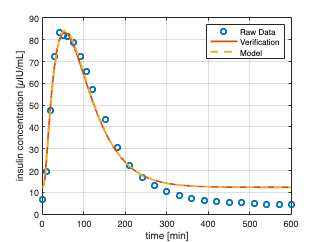

out = sim('iam_sim.slx');
clf(figure(2)); figure(2)
plot(t, i, 'o','Linewidth',2); hold on
plot(out0.I_est(:,1), out0.I_est(:,2),'Linewidth',2)
plot(out.I_est(:,1), out.I_est(:,2), '--', 'Linewidth',2)
xlabel('time [min]'); ylabel('insulin concentration [µIU/mL]')
legend('Raw Data', 'Verification', 'Model');

## Index Insuline Sensitivity and Duration of Action

### 2. Plot data from the PD

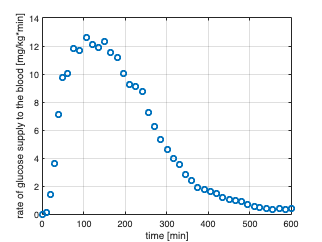

figure
plot(t_ra, ra, 'o','Linewidth',2)
xlabel('time [min]'); ylabel('rate of glucose supply to the blood [mg/kg*min]')

Initialize variables

Vg = 1.467;         % [dL/kg]
Sg = 0;             % [1/min]
Ib = I0;          % [µIU/mL]
Gb = 153;           % [mg/dL]
G0 = Gb;            % [mg/dL]
X0 = 0.00;             % [1/min]

G = Gb * ones(length(ra),1);

Initialize optimized variables

Si = 0.00159;      % [mL/(µIU*min)]
p2 = 0.0106;       % [1/min]
theta0 = [Si p2];

Set SIMULINK initials

input_sim.time = t_ra;
input_sim.signals.values = ra;
input_sim.signals.dimensions = 1;

### Verify the simulation scheme

set_param('iam_sim/BMM', 'Commented', 'off')
set_param('iam_sim/BMM/Gain_Sip2', 'Gain', num2str(Si*p2))
set_param('iam_sim/BMM/Gain_p2', 'Gain', num2str(p2))

out0 = sim('iam_sim.slx');

### Implement a identification method of Insuline Sensitivity Index

Set optimization options

opts = optimset('Display', 'iter', 'MaxIter', 250);

Run identification

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          64160.8         
     1            3          64160.8         initial simplex
     2            5          64160.8         contract inside
     3            7          61320.5         contract inside
     4            9          60065.2         contract inside
     5           11          60065.2         contract outside
     6           13          59965.5         contract inside
     7           15          59655.6         reflect
     8           17          59650.4         contract inside
     9           19          59650.4         contract inside
    10           21          59594.2         contract inside
    11           23          59578.2         contract inside
    12           25          59578.2         contract inside
    13           26          59578.2         reflect
    14           28          59575.4         contract inside
    15           30          59572.5         contract insi

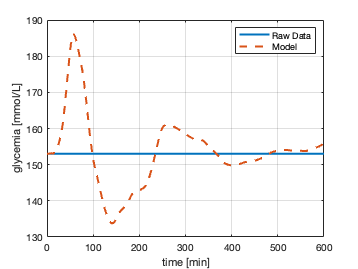

    27           56          59571.8         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



x_opt =     0.0016    0.0108


fval = 5.9572e+04

exitflag = 1

output = struct with fields:
    iterations: 27
     funcCount: 56
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


[x_opt, fval, exitflag, output] = ...
    fminsearch(@objFcn_PD, theta0, opts, G(1:end), t_ra(1:end), 1)


Si_opt = x_opt(1);
p2_opt = x_opt(2);

Plot simulation output **Glucose Supply Rate**

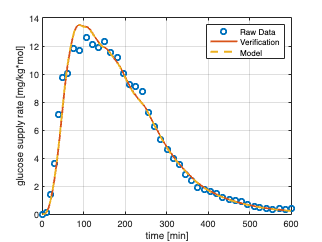

out = sim('iam_sim.slx');
clf(figure(3)); figure(3)
plot(t_ra, ra, 'o','Linewidth',2); hold on
plot(out0.Ra_est(:,1), out0.Ra_est(:,2),'Linewidth',2)
plot(out.Ra_est(:,1), out.Ra_est(:,2), '--', 'Linewidth',2)
xlabel('time [min]'); ylabel('glucose supply rate [mg/kg*mol]')
legend('Raw Data', 'Verification', 'Model');

Plot simulation output **Glycemia**

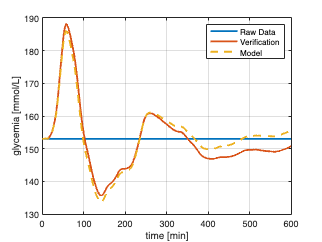

data = interp1(t_ra, G, out.G_est(:,1));
clf(figure(4)); figure(4)
plot(out0.G_est(:,1),data,'Linewidth',2); hold on
plot(out0.G_est(:,1), out0.G_est(:,2),'Linewidth',2)
plot(out.G_est(:,1), out.G_est(:,2), '--', 'Linewidth',2)
xlabel('time [min]'); ylabel('glycemia [mmol/L]')
legend('Raw Data', 'Verification', 'Model');